1. Sharpen the following image by applying the following: 

    a) Unsharp Masking

    b) High Boost Filtering

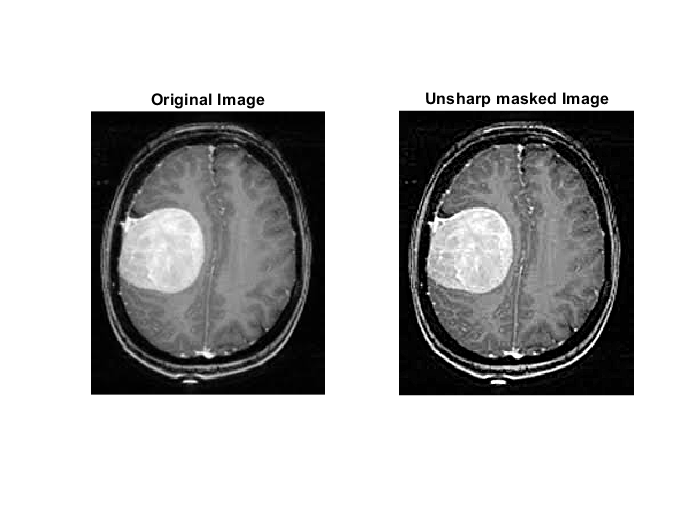

% a)
I1 = imread('tumor.png');
unsharpM = imsharpen(I1,'Radius', 2, 'Amount',1);
subplot(1,2,1);imshow(I1);title('Original Image');
subplot(1,2,2);imshow(unsharpM);title('Unsharp masked Image');

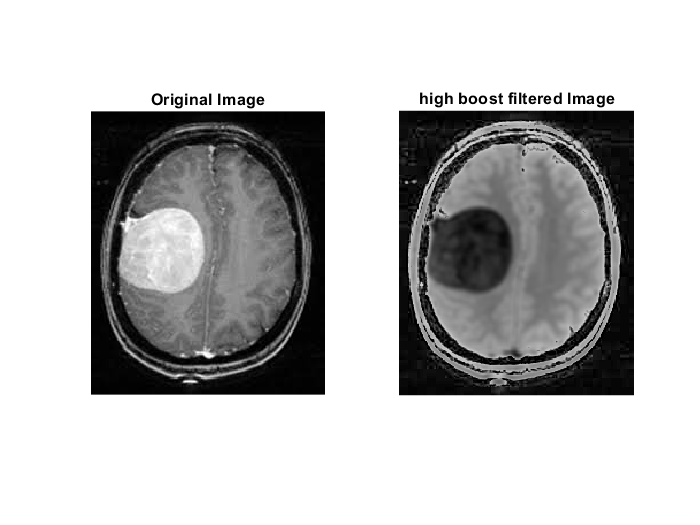


%% b)
A = 4;
avg = fspecial('average', [5,5]);
blur = imfilter(I1, avg);
hbf = (A-1)*I1+I1-blur;
figure();
subplot(1,2,1);imshow(I1);title('Original Image');
subplot(1,2,2);imshow(hbf);title('high boost filtered Image');

2. Sharpen the following image using the concept of Laplacian Filtering. 

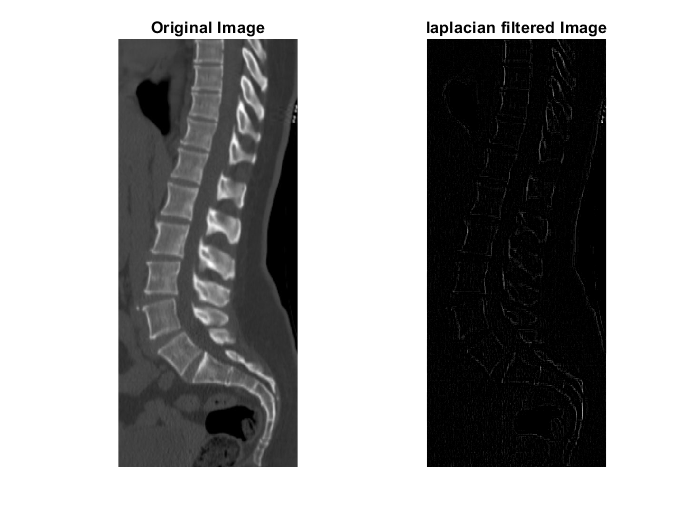

I2 = imread('Spine_CT.png');

lmask = [-1 -1 -1; -1 8 -1; -1 -1 -1];
laplacian = imfilter(I2, lmask);
figure();
subplot(1,2,1);imshow(I2);title('Original Image');
subplot(1,2,2);imshow(laplacian);title('laplacian filtered Image');

3. Use **Roberts-cross** operators to detect the edge of the following image. 

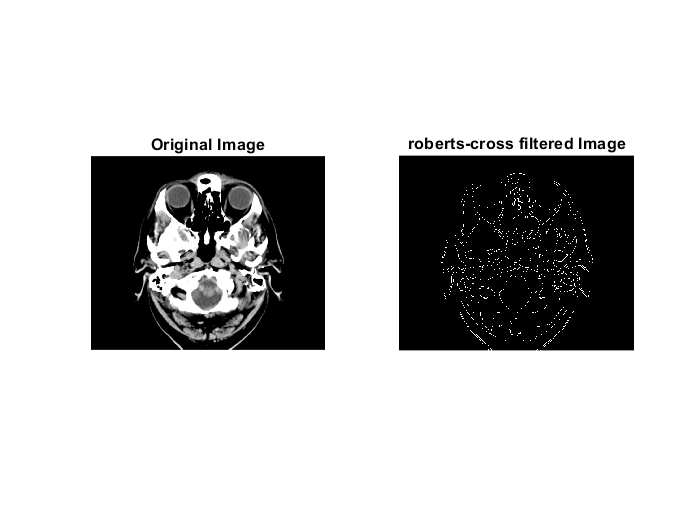

I3 = imread('Head_CT_Scan.png');

grayI = rgb2gray(I3);
roberts = edge(grayI, 'Roberts');
subplot(1,2,1);imshow(I3);title('Original Image');
subplot(1,2,2);imshow(roberts);title('roberts-cross filtered Image');

4. Use Sobel operators to detect the edge of the image from problem 3. 

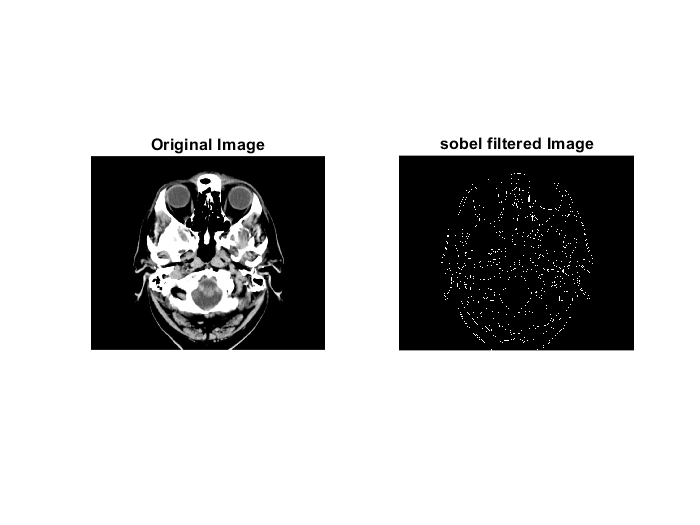

sobel = edge(grayI, 'Sobel');
subplot(1,2,1);imshow(I3);title('Original Image');
subplot(1,2,2);imshow(sobel);title('sobel filtered Image');

5. Use **Prewitt** operators to detect the edge of the image from problem 3. 

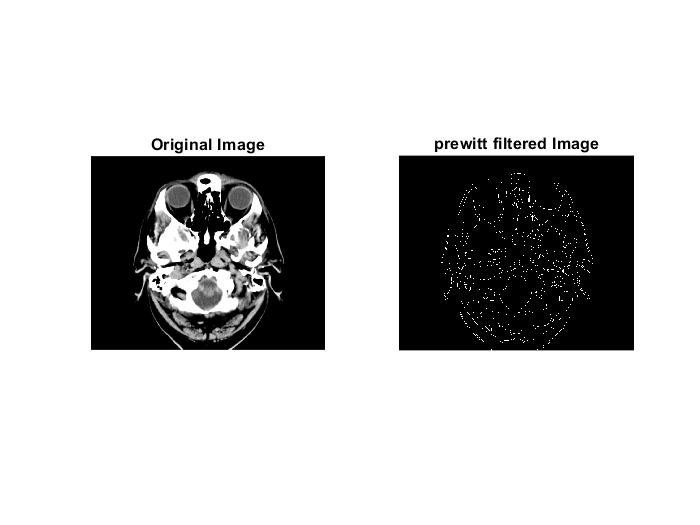

prewitt = edge(grayI, 'Prewitt');
figure();
subplot(1,2,1);imshow(I3);title('Original Image');
subplot(1,2,2);imshow(prewitt);title('prewitt filtered Image');

6. Show performance comparison among High Boost, Unsharp, Laplacian Roberts-cross, Sobel and Prewitt filtering for edge detection – find out which one is better for the given images.

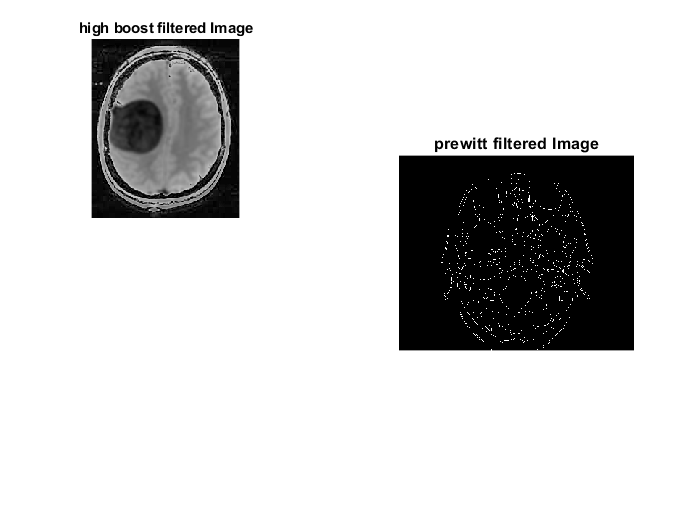

subplot(2,3,1); imshow(hbf); title('high boost filtered Image');

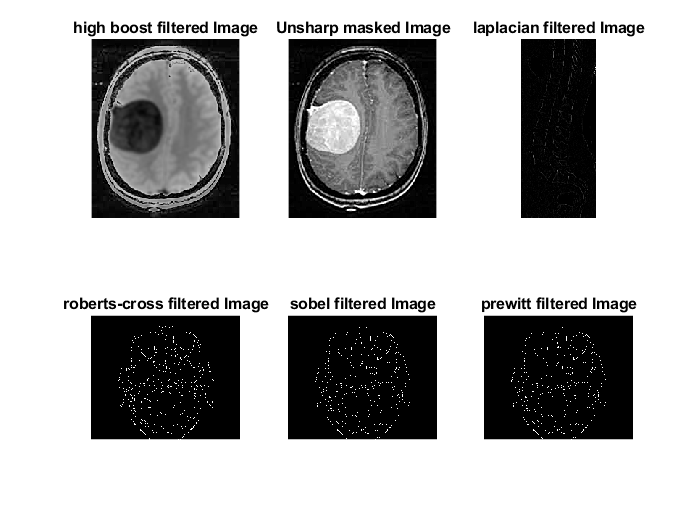

subplot(2,3,2); imshow(unsharpM); title('Unsharp masked Image');
subplot(2,3,3); imshow(laplacian); title('laplacian filtered Image');
subplot(2,3,4); imshow(roberts); title('roberts-cross filtered Image');
subplot(2,3,5); imshow(sobel); title('sobel filtered Image');
subplot(2,3,6); imshow(prewitt); title('prewitt filtered Image');

### **2nd Way to solve problem............**

1. Sharpen the following image by applying the following: 

    a) Unsharp Masking

    b) High Boost Filtering

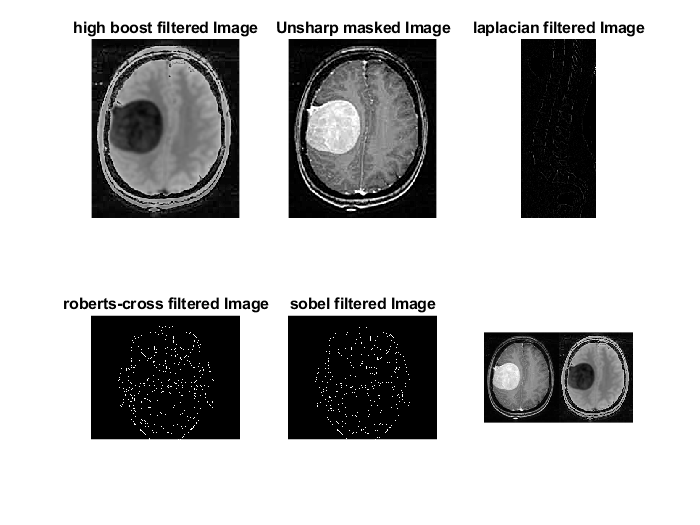

%% a)
I1 = imread('tumor.png');

avg = fspecial('average', [5,5]);
blur = imfilter(I1, avg);
srp = imsubtract(I1, blur);
x = imadd(I1, srp);
imshowpair(I1, x, "montage");

%% b)
A = 4;
hbf = (A-1) * I1 + I1 - blur;
imshowpair(I1, hbf, "montage");

2. Sharpen the following image using the concept of Laplacian Filtering. 

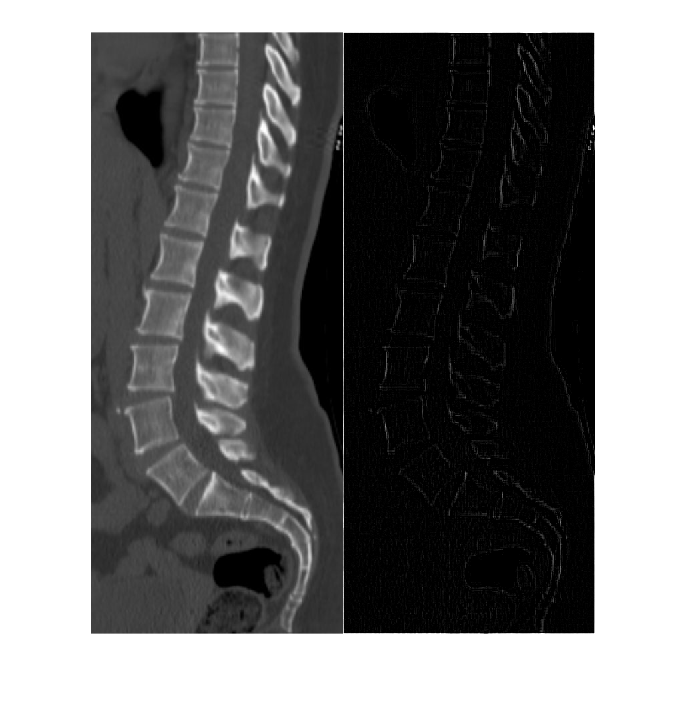

I2 = imread('Spine_CT.png');

lmask = [-1 -1 -1; -1 8 -1; -1 -1 -1];
l = imfilter(I2, lmask);
figure, imshowpair(I2, l,"montage");

3. Use **Roberts-cross** operators to detect the edge of the following image. 

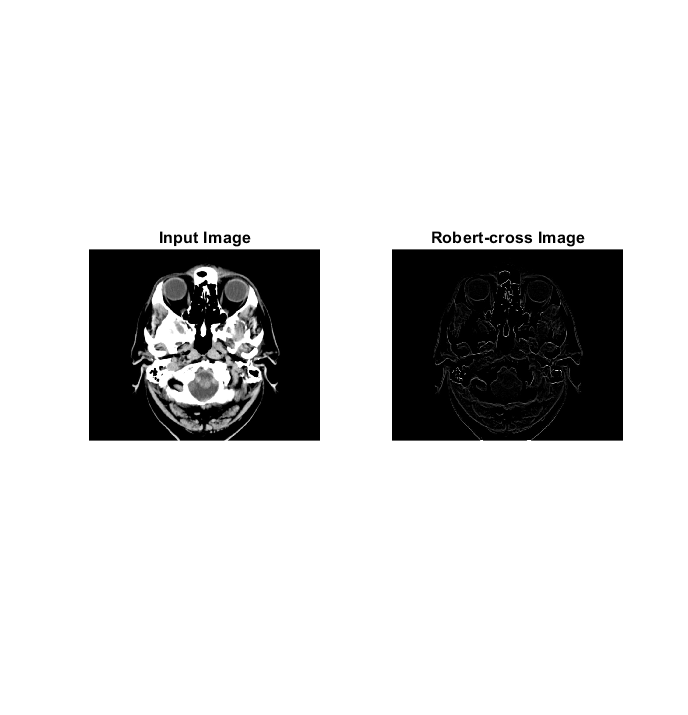

I3 = imread('Head_CT_Scan.png');
grayI = rgb2gray(I3);

x_mask = [1 0; 0 -1];
y_mask = [0 1; -1 0];

xR = imfilter(grayI,x_mask);
yR = imfilter(grayI,y_mask);

add_rc = imadd(xR,yR);

subplot(1,2,1);imshow(I3);title('Input Image');
subplot(1,2,2);imshow(add_rc);title('Robert-cross Image');

4. Use Sobel operators to detect the edge of the image from problem 3. 

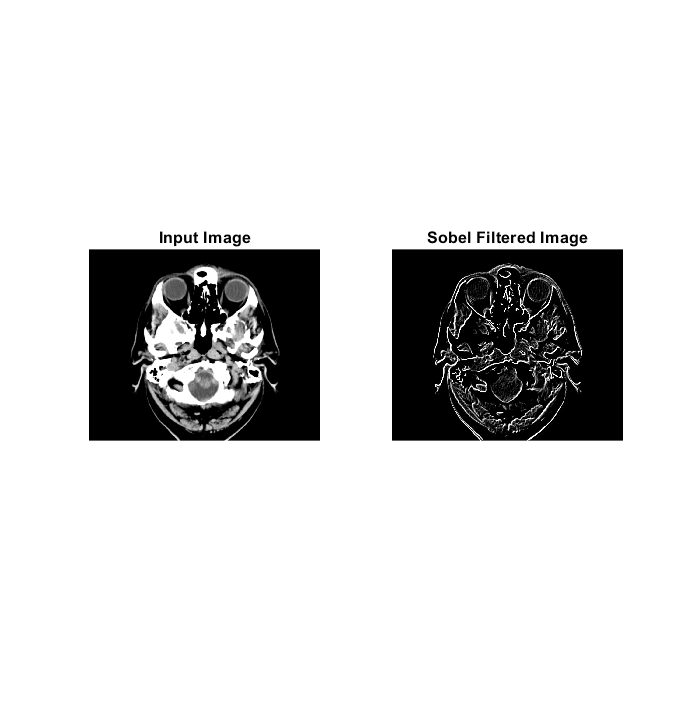

x_mask = [-1 -2 -1; 0 0 0; 1 2 1];
y_mask = [-1 0 1; -2 0 2; -1 0 1];

sobel1 = imfilter(grayI, x_mask);
sobel2 = imfilter(grayI, y_mask);

add_sobel=imadd(sobel1,sobel2);

subplot(1,2,1);imshow(I3);title('Input Image');
subplot(1,2,2);imshow(add_sobel);title('Sobel Filtered Image');

5. Use **Prewitt** operators to detect the edge of the image from problem 3. 

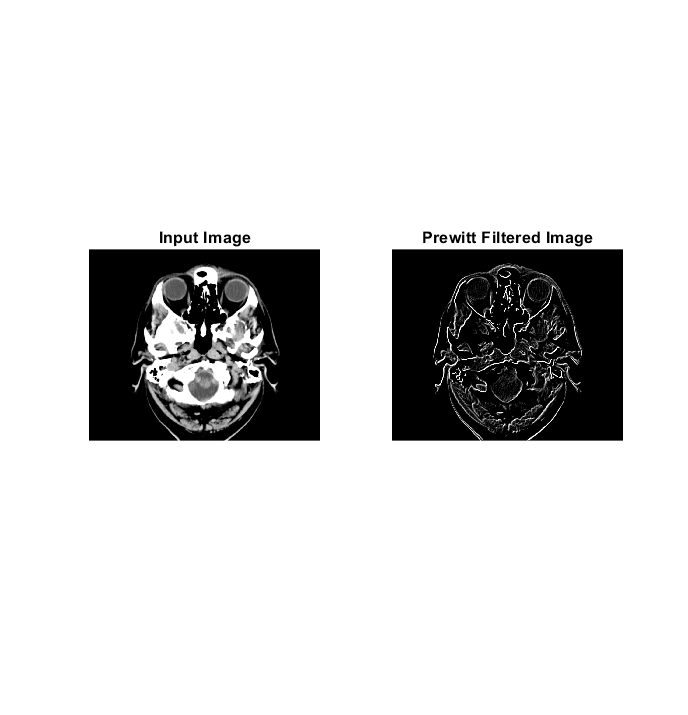

x_mask = [-1 -1 -1; 0 0 0; 1 1 1];
y_mask = [-1 0 1; -1 0 1; -1 0 1];

prewitt1 = imfilter(grayI, x_mask);
prewitt2 = imfilter(grayI, y_mask);

add_pre = imadd(prewitt1,prewitt2);

subplot(1,2,1);imshow(I3);title('Input Image');
subplot(1,2,2);imshow(add_pre);title('Prewitt Filtered Image');

6. Show performance comparison among High Boost, Unsharp, Laplacian Roberts-cross, Sobel and Prewitt filtering for edge detection – find out which one is better for the given images.

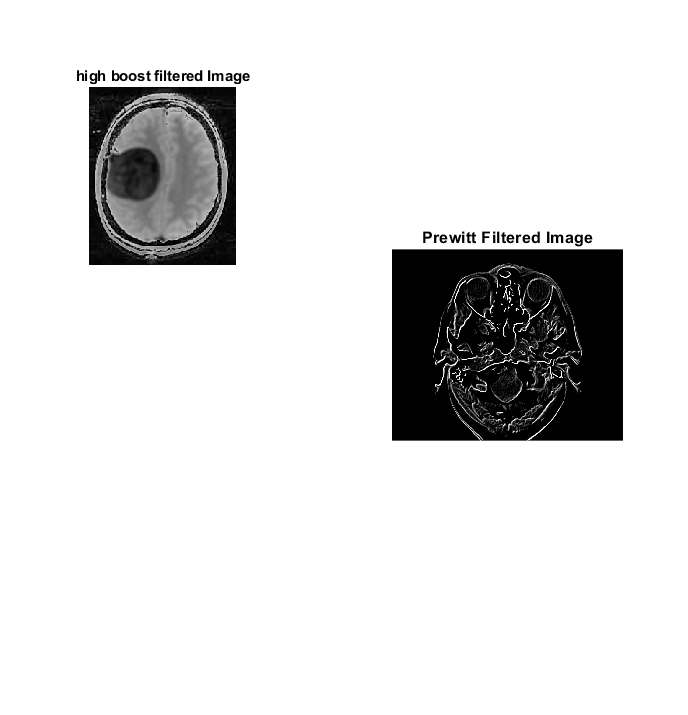

subplot(2,3,1); 
imshow(hbf); 
title('high boost filtered Image');

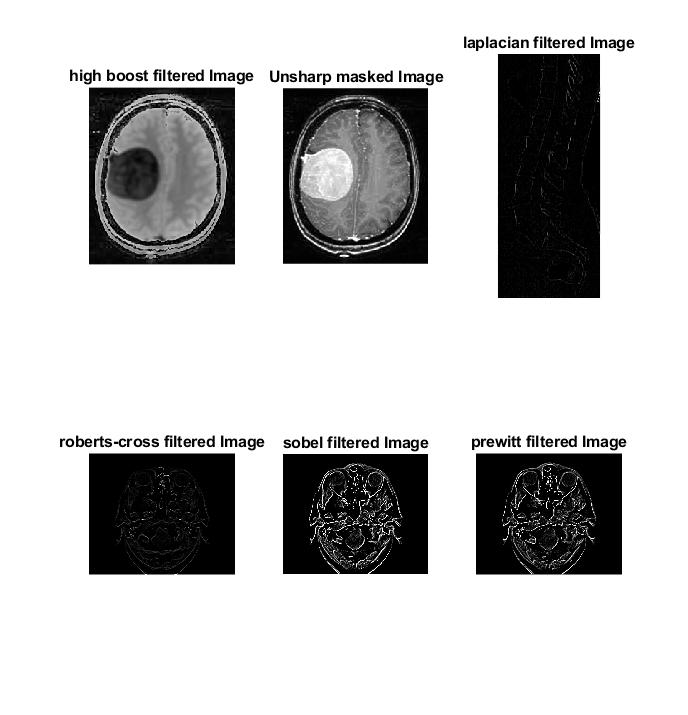


subplot(2,3,2); 
imshow(x); 
title('Unsharp masked Image');

subplot(2,3,3); 
imshow(l); 
title('laplacian filtered Image');

subplot(2,3,4); 
imshow(add_rc); 
title('roberts-cross filtered Image');

subplot(2,3,5); 
imshow(add_sobel); 
title('sobel filtered Image');

subplot(2,3,6);
imshow(add_pre); title('prewitt filtered Image');